# GUNK - fullfishmonger

## fm = datastructure

fullfishmonger code selects folder of csv files generated by deeplabcut video tracking analysis

### load data

deeplabcut PC

load('C:\Users\DeepLabCut\Documents\MATLAB\fm.mat');
load('C:\Users\DeepLabCut\Documents\MATLAB\fmv.mat');
 
addpath('C:\Users\DeepLabCut\SparkleShare\FishCodeGH\Gallman')

### save data

deeplabcut PC

save('C:\Users\DeepLabCut\Documents\MATLAB\fm.mat', 'fm');jj
save('C:\Users\DeepLabCut\Documents\MATLAB\fmv.mat', 'fmv');


### add to data structure

k = 14;
fm(k) = fullfishmonger;

# fm(k)

Values of k refer to individual fish - 4 fish tracked per trial

#### worm fed

*Pachon*

k = 01; LL    PachonSFwormLD-Jan-21-2022

k = 02; LR    PachonSFwormLD-Jan-21-2022

k = 03; UL    PachonSFwormLD-Jan-21-2022

*Surface fish*

k = 04; UR    PachonSFwormLD-Jan-21-2022

*Pachon*

k = 05; LL     PachonSFwormDD-Feb-01-2022

k = 06; LR    PachonSFwormDD-Feb-01-2022

k = 07; UL     PachonSFwormDD-Feb-01-2022

*Surface fish*

k = 08; UR     PachonSFwormDD-Feb-01-2022

#### day flakes

*Surface fish*

k = 09; LL    SFdayflakesDD-Feb-24-2022

k = 10; LR    SFdayflakesDD-Feb-24-2022

k = 11; UL    SFdayflakesDD-Feb-24-2022

k = 12;UR    SFdayflakesDD-Feb-24-2022

#### Night flakes

*Pachon*

k = 13; LL    PachonnightflakesDD-Feb-28-2022

k = 14; LR    PachonnightflakesDD-Feb-28-2022

### Calculate velocity

fmv(k).ss = fmfilteredvelocity(fm(k));

notes: plotting std or variance looks the same as the average velocity plot, just different y-axis scale

### Generate time and light transistion vectors

fmv(k).timfo = fmtims(fmv(k));

fmv(k).sx = fmfileredmidxings(fm(k));

Execution of script fmfileredmidxings as a function is not supported:
/Users/eric/SparkleShare/github.com/FishCodeGH/Gallman/fmfileredmidxings.m

### Plot

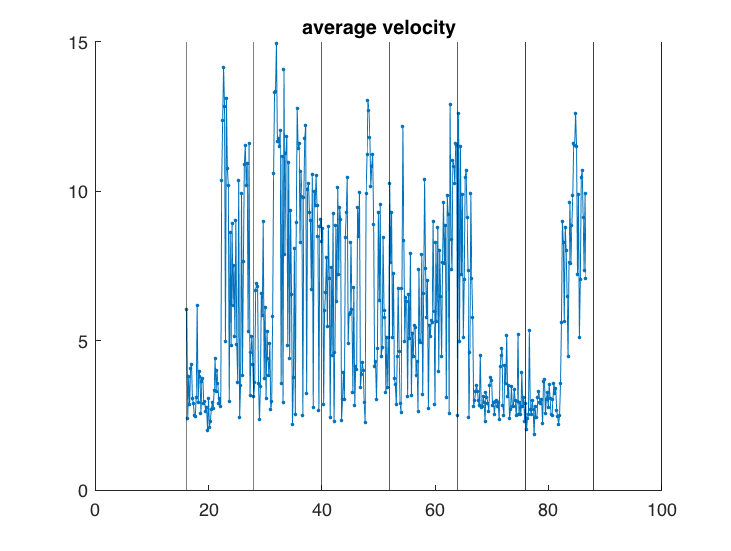

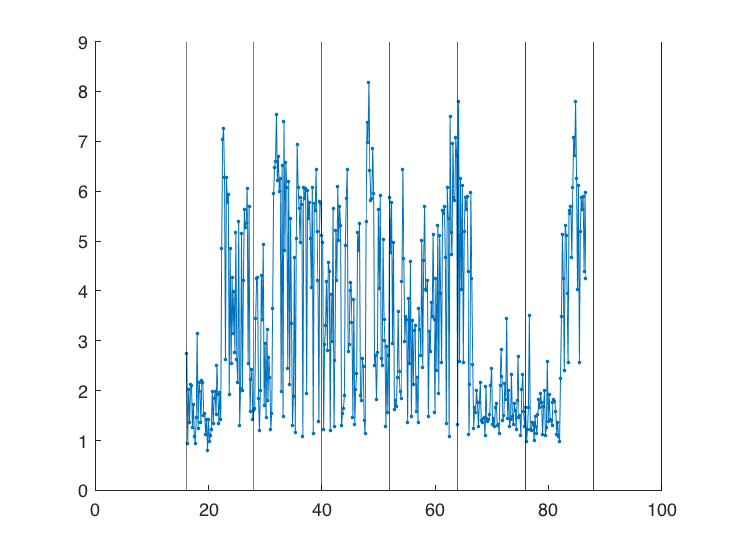

fmvplotter(fmv(k))

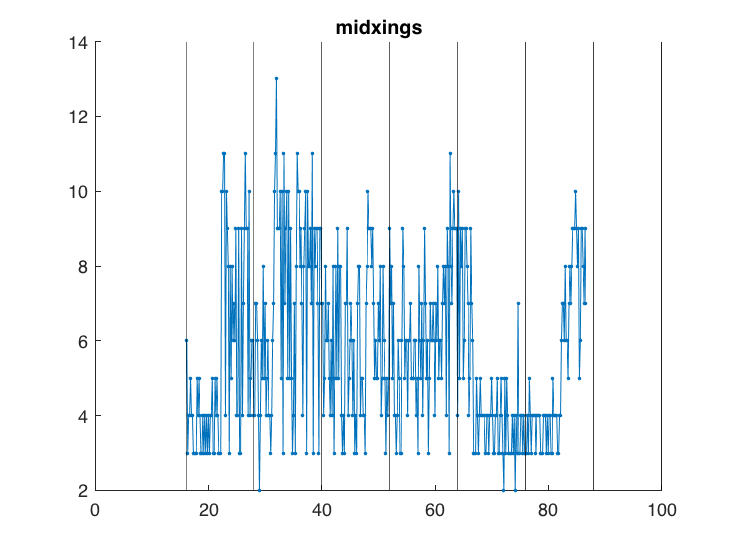

fmvmidxingplotter(fmv(k))

j = 3; %1:1000
fmfilteredpositionplotter(fmv(k),j)